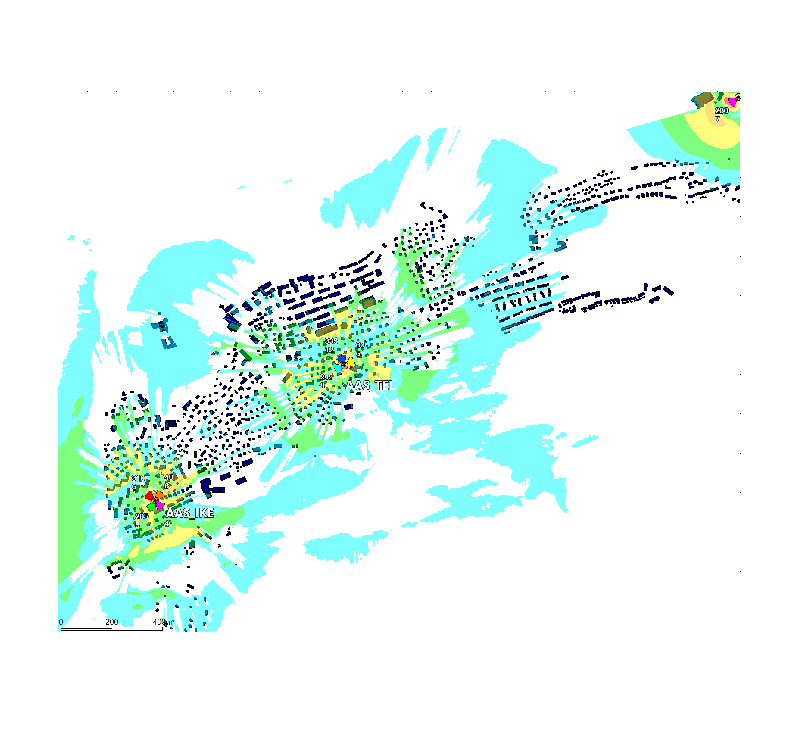

mc = imread('aas n78 sig cropped.png');
imshow(mc);

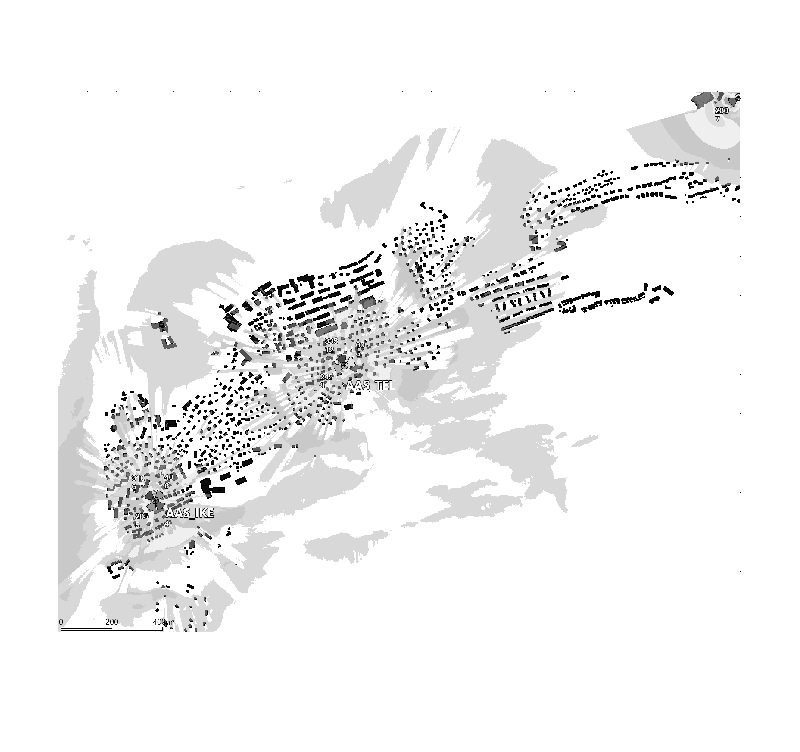

Igr = rgb2gray(mc);
imshow(Igr, []);

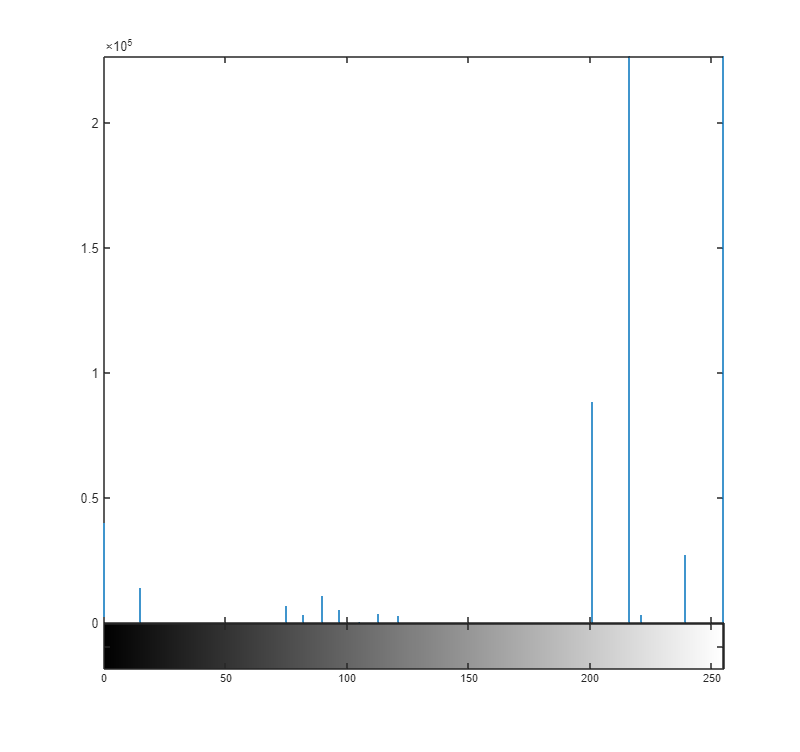

imhist(Igr);


thisIntensity = impixel(Igr, 50, 50);
thisIntensity

thisIntensity =    255   255   255


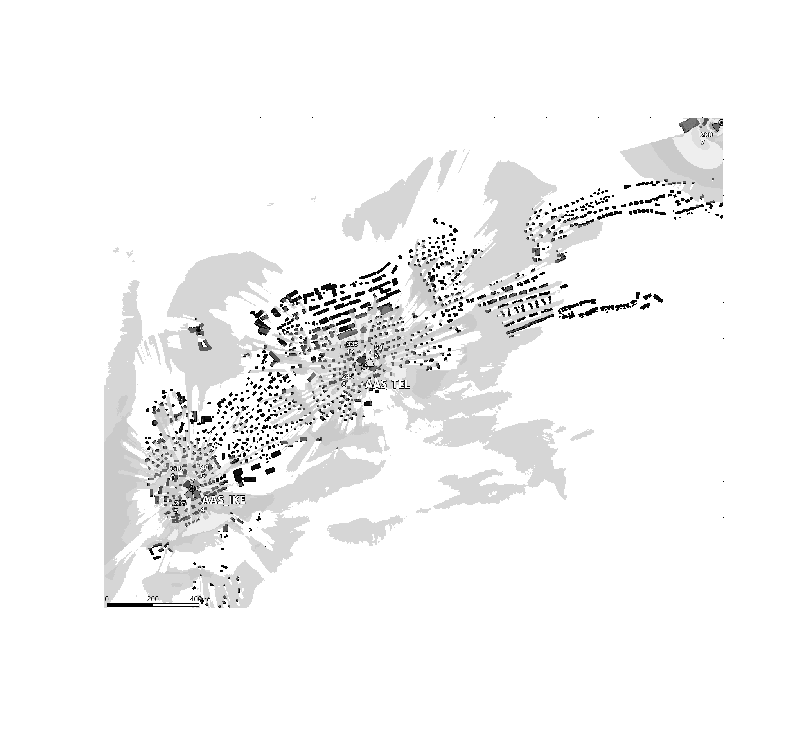

[X, map] = gray2ind(Igr, 64);
imshow(X, map);

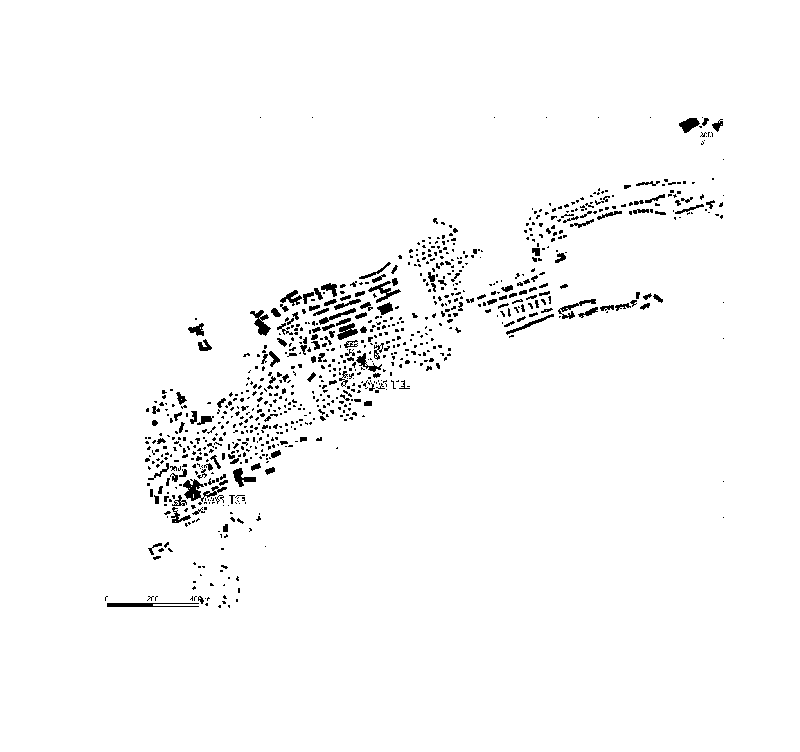

indices = find(abs(X)>40);
X(indices) = 255;

indices2 = find(abs(X)<40);
X(indices2) = 0;

imshow(X, map);

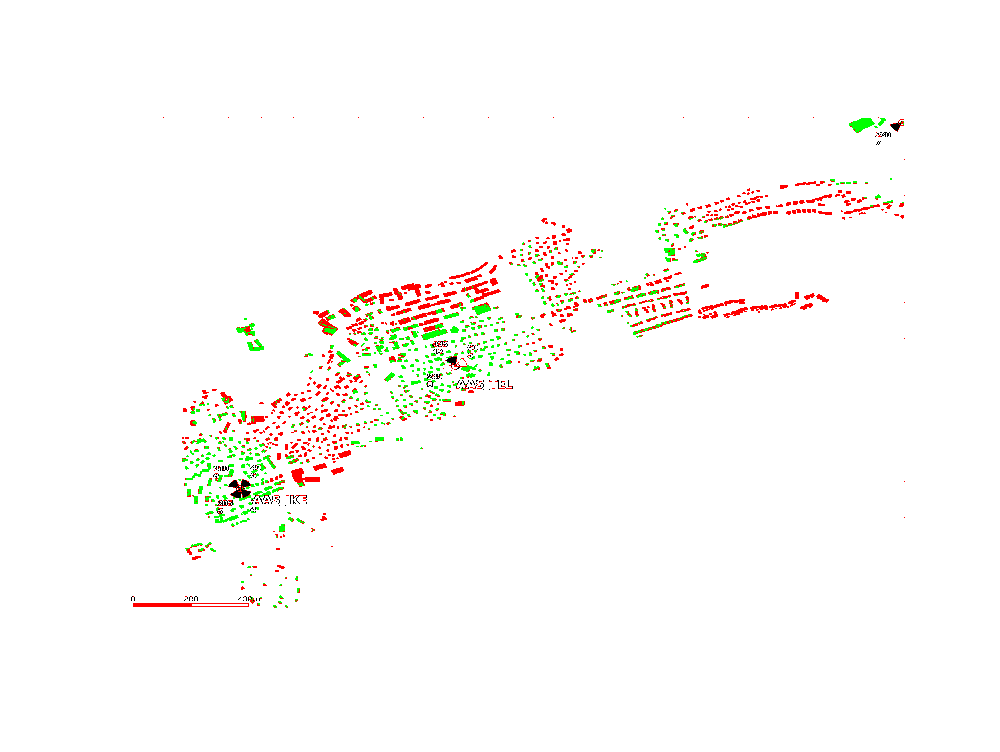

X;
[row,col] = find(abs(X)<1);
[row,col] ;
rgbColor = impixel(mc, col, row);

Threshold = -120;
Penloss = -0;
F = zeros(min(size(X)),max(size(X)),3);
F(:,:,1) = X(:,:);
F(:,:,2) = X(:,:);
F(:,:,3) = X(:,:);
NewImage = X;

for k = 1:max(size(rgbColor))
    
            if rgbColor(k,1) == 128 && rgbColor(k,2) == 0
                Signal = -70+Penloss;
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                end
            end

            if rgbColor(k,1) == 127 && (rgbColor(k,2) == 84 || rgbColor(k,2) == 63) || rgbColor(k,2) == 97 || (rgbColor(k,1) == 127 && (rgbColor(k,2) == 84 || rgbColor(k,2) == 63 || rgbColor(k,2) == 94) && rgbColor(k,3) == 63)
                Signal = -80+Penloss;
                                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;                   
                end
            end

            if (rgbColor(k,1) == 128 || rgbColor(k,1) == 127) && (rgbColor(k,2) == 128 || rgbColor(k,2) == 127)
                Signal = -90+Penloss;
                                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;                   
                end
            end
            if rgbColor(k,1) == 0 && rgbColor(k,2) == 128 && (rgbColor(k,3) == 0 || rgbColor(k,3) == 63)
                Signal = -100+Penloss;
                                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;                   
                end
            end

            if rgbColor(k,2) == 128 && rgbColor(k,3) == 128
                Signal = -110+Penloss;
                                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;                   
                end
            end
            if rgbColor(k,2) == 128 && rgbColor(k,3) == 191
                Signal = -120+Penloss;
                                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;                   
                end
            end
            if rgbColor(k,3) == 128 && rgbColor(k,2) == 0
                Signal = -130+Penloss;
                                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;                  
                end
            end

            if rgbColor(k,1) == 0 && rgbColor(k,2) == 0 && rgbColor(k,3) == 0
                NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;   
            end

end
imshow(F,map)

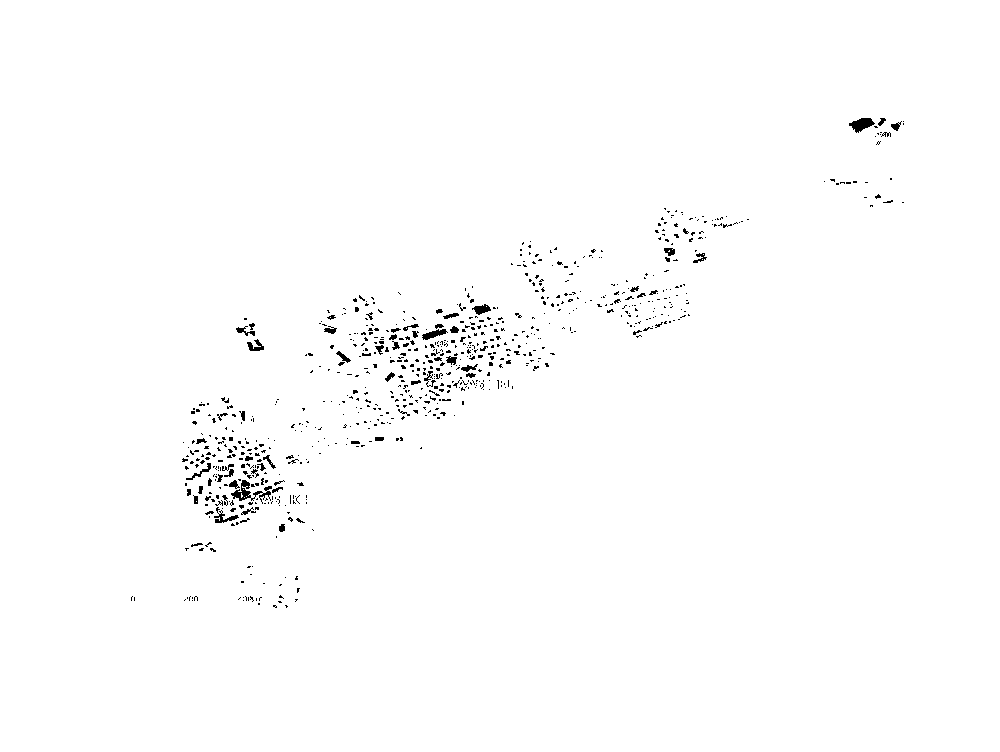

imshow(NewImage)